humanInfo = getgenpept('BAC16799')

humanInfo = struct with fields:
                LocusName: 'BAC16799'
      LocusSequenceLength: '393'
     LocusNumberofStrands: ''
            LocusTopology: 'linear'
        LocusMoleculeType: ''
     LocusGenBankDivision: 'PRI'
    LocusModificationDate: '01-APR-2003'
               Definition: 'P53 [Homo sapiens].'
                Accession: 'BAC16799'
                  Version: 'BAC16799.1'
                       GI: ''
                  Project: []
                   DBLink: ' DBSOURCE    accession AB082923.1'
                 Keywords: []
                  Segment: []
                   Source: 'Homo sapiens (human)'
           SourceOrganism: [4×65 char]
                Reference: {[1×1 struct]  [1×1 struct]}
                  Comment: []
                 Features: [39×63 char]
                      CDS: [1×1 struct]
                 Sequence: 'meepqsdpsvepplsqetfsdlwkllpennvlsplpsqamddlmlspddieqwftedpgpdeaprmpeaaprvapapaaptpaapapapswplsssvpsqktyqgsygfrlgflhsgtaksvtctyspalnkmf

mouseInfo = getgenpept('AAA39883')

mouseInfo = struct with fields:
                LocusName: 'AAA39883'
      LocusSequenceLength: '381'
     LocusNumberofStrands: ''
            LocusTopology: 'linear'
        LocusMoleculeType: ''
     LocusGenBankDivision: 'ROD'
    LocusModificationDate: '27-APR-1993'
               Definition: 'p53 [Mus musculus].'
                Accession: 'AAA39883'
                  Version: 'AAA39883.1'
                       GI: ''
                  Project: []
                   DBLink: ' DBSOURCE    locus MUSP53C accession M13874.1'
                 Keywords: []
                  Segment: []
                   Source: 'Mus musculus (house mouse)'
           SourceOrganism: [4×66 char]
                Reference: {[1×1 struct]  [1×1 struct]}
                  Comment: 'Method: conceptual translation.'
                 Features: [35×66 char]
                      CDS: [1×1 struct]
                 Sequence: 'mtameesqsdislelplsqetfsglwkllppedilpsphcmddlllpqdveeffegpsealrvsgapaaqdpvtetpgpvapapa

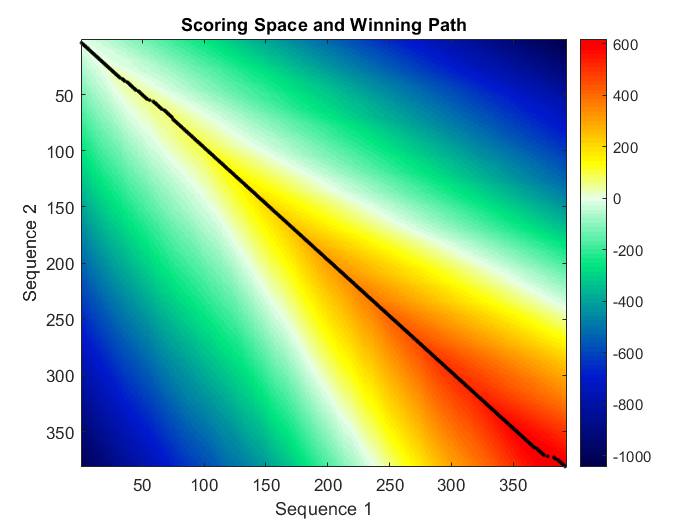


seqdotplot(humanInfo, mouseInfo);
set(gcf, 'name', 'Similarity Recurrence Plot')

[score, alignment] = nwalign(humanInfo, mouseInfo, 'Showscore', true);

showalignment(alignment);

score

score = 607.3333

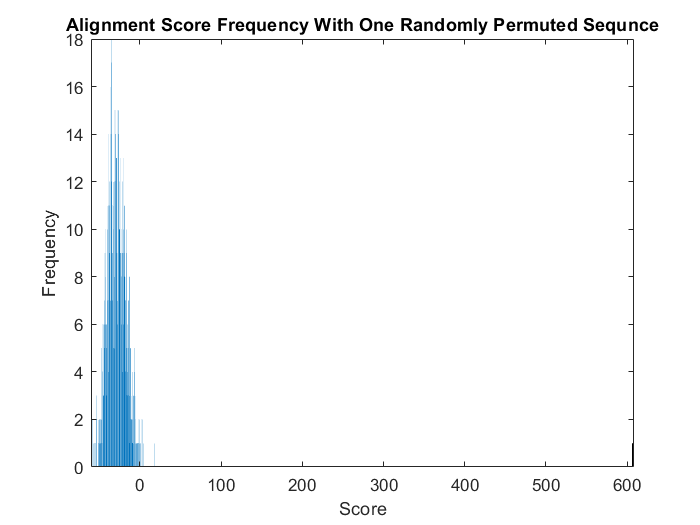


permLength = length(mouseInfo.Sequence); % the mouse sequence is shorter than the human sequence so less computation here
numOfPerms = 1000; % can be any size as long as its big enough for statistical significance
generatedSequences = strings(1, numOfPerms); % for sequences which are permutations
generatedSequences2 = strings(1, numOfPerms); % for sequences based off original distributtion
for i = 1 : numOfPerms % generating sequences
    perm = randperm(permLength);
    permutedPeptideSequence = "";
    for j = 1 : permLength
       permutedPeptideSequence = strcat(permutedPeptideSequence, mouseInfo.Sequence(perm(j)));
    end
    count = aacount(mouseInfo.Sequence); 
    randSequence = randseq(numel(mouseInfo.Sequence), 'FromStructure', count);
    generatedSequences(i) = permutedPeptideSequence;
    generatedSequences2(i) = randSequence; 
end
scores = zeros(2, numel(generatedSequences));
scores2 = zeros(2, numel(generatedSequences2));
counter = 1;
counter2 = 1;
for i = 1 : numel(scores)/2 % summing frequencies
    currentScore = nwalign(humanInfo.Sequence, generatedSequences(i));
    currentScore2 = nwalign(humanInfo.Sequence, generatedSequences2(i));
    matched = false;
    matched2 = false;
    for j = 1 : numel(scores)/2
        if(currentScore == scores(2, j))
            scores(1, j) = scores(1, j)+1;
            matched = true;
        end
    end
    for j = 1 : numel(scores2)/2
        if(currentScore2 == scores2(2, j))
            scores2(1, j) = scores2(1, j)+1;
            matched2 = true;
        end
    end
    if(matched == false)
        scores(1, counter) = 1;
        scores(2, counter) = currentScore;
        counter = counter+1;
    end
    if(matched2 == false)
        scores2(1, counter2) = 1;
        scores2(2, counter2) = currentScore2;
        counter2 = counter2+1;
    end
end
counter = 0;
counter2 = 0;
for i = 1 : numel(scores)/2
    if(scores(2, i) == 0)
        break;
    else
        counter = counter+1;
    end
end
for i = 1 : numel(scores2)/2
    if(scores2(2, i) == 0)
        break;
    else
        counter2 = counter2+1;
    end
end
finalScores = zeros(1, counter);
finalScores2 = zeros(1, counter2);
for i = 1 : numel(finalScores)
    finalScores(1, i) = scores(1, i);
    finalScores(2, i) = scores(2, i);
end
for i = 1 : numel(finalScores2)
    finalScores2(1, i) = scores2(1, i);
    finalScores2(2, i) = scores2(2, i);
end
figure % plotting
bar(finalScores(2, :), finalScores(1, :));
hold on;
bar(score, 1);
title('Alignment Score Frequency With One Randomly Permuted Sequnce');
xlabel('Score');
ylabel('Frequency');
hold off;

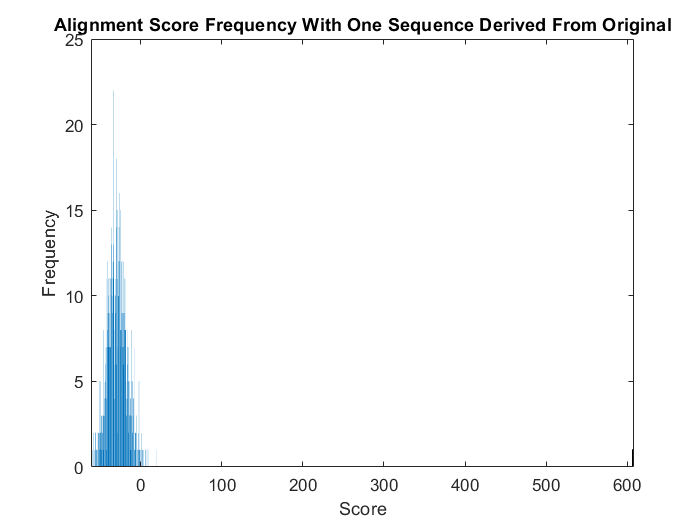

figure
bar(finalScores2(2, :), finalScores2(1, :));
title('Alignment Score Frequency With One Sequence Derived From Original');
xlabel('Score');
ylabel('Frequency');
hold on;
bar(score, 1);
hold off;